# School Attendance Model

### 41082 Introduction to Data Engineering - Autumn 2022

Contributers:

- 13901057 - Georgette Bashour 

- 13246638 - Jake Roeleven

- 24466827 - Samantha Tropea  

- 14251235 - Anurag Majumder

**Model Description:**

Modelling school attendance based on contexual factors in the schools local area.

## Stage 1: Pre Process Data

% Read in all tables of csv data
all_schools_table = readtable("datasets\relevant\master_schools_dataset.csv", "TextType", "string", ReadVariableNames=true);

schools_attendance_table = readtable("datasets\relevant\school_attendance_dataset.csv", "TextType", "string", ReadVariableNames=true);

motor_vehicles_dataset = readtable("datasets\relevant\motor_vehicle_ownership_dataset.csv", "TextType", "string", ReadVariableNames=true);
bachelors_degree_dataset = readtable("datasets\relevant\postgraduate_education_dataset.csv", "TextType", "string", ReadVariableNames=true);
houshold_income_dataset = readtable("datasets\relevant\households_postcode_dataset.csv", "TextType", "string", ReadVariableNames=true);
single_parents_dataset = readtable("datasets\relevant\postcode_famlies_dataset.csv", "TextType", "string", ReadVariableNames=true);
private_health_insurance_dataset = readtable("datasets\relevant\postcode_tax_datasets.csv", "TextType", "string", ReadVariableNames=true);

retention_rate_dataset = readtable("datasets\relevant\sa4_retention_rates_dataset.csv", "TextType", "string", ReadVariableNames=true);

crime_rate_dataset = readtable("datasets\relevant\crime_dataset.csv", "TextType", "string", ReadVariableNames=true);
education_score_dataset = readtable("datasets\relevant\postcode_abs_scores_dataset.csv", "TextType", "string", ReadVariableNames=true);

better_education_score_dataset = readtable("datasets\relevant\better_education_scores_dataset.csv", "TextType", "string", ReadVariableNames=true);

sa4_regions_map = readtable("datasets\relevant\sa4_grouping_map.xlsx", "TextType", "string", ReadVariableNames=true);

%%% Calculate Factors not yet avalible in the data %%%

% Calculate Percentage of Postcode with Bachelors Degrees
bachelors_degree_dataset.bachelor_pct = bachelors_degree_dataset.bachelor ./ bachelors_degree_dataset.total_population;

% Calculate Percentage of Familes in Postcode with Single Parent
single_parents_dataset.single_parent_families_pct = single_parents_dataset.Tot_One_parent_fam ./ single_parents_dataset.Tot_Tot;

% Calculate Percentage of People with Private Health Insurance
% First we need to join total postcode population
total_popualtion_dataset = readtable("datasets\relevant\population_breakdown_datasets.csv", "TextType", "string", ReadVariableNames=true);
private_health_insurance_dataset = outerjoin(private_health_insurance_dataset, total_popualtion_dataset, "Keys", "postcode", "MergeKeys", true);
private_health_insurance_dataset = rmmissing(private_health_insurance_dataset, 1);
private_health_insurance_dataset.private_health_insurance_pct = private_health_insurance_dataset.privateHealthInsuranceNo_ ./ private_health_insurance_dataset.population;

% Calculate Crime Rates
% First need to join total postcode population
crime_rate_dataset = outerjoin(crime_rate_dataset, total_popualtion_dataset, "Keys", "postcode", "MergeKeys", true);
crime_rate_dataset = rmmissing(crime_rate_dataset, 1);
crime_rate_dataset.crimes_per_person = crime_rate_dataset.crimes ./ crime_rate_dataset.population;

% Recognise Selective Schools (Selective/Partially = 1, Not Selective = 0)
idx = ismember(all_schools_table.Selective_school, "Not Selective");
all_schools_table.Selective_school(idx, :) = 0;
idx = ismember(all_schools_table.Selective_school, "Partially Selective");
all_schools_table.Selective_school(idx, :) = 0.5;
idx = ismember(all_schools_table.Selective_school, "Fully Selective");
all_schools_table.Selective_school(idx, :) = 1;
all_schools_table.Selective_school = str2double(all_schools_table.Selective_school);

% Recognise Coed Schools (Coed = 1, Not Coed = 0)
idx = ismember(all_schools_table.School_gender, "Coed");
all_schools_table.School_gender(~idx, :) = 1;
all_schools_table.School_gender(idx, :) = 0;
all_schools_table.School_gender = str2double(all_schools_table.School_gender);

% Recognise Remotness of Schools (Remote = 1 on Sliding Scale to 0)
idx = ismember(all_schools_table.ASGS_remoteness, "Remote Australia");
all_schools_table.ASGS_remoteness(idx, :) = 1;
idx = ismember(all_schools_table.ASGS_remoteness, "Outer Regional Australia");
all_schools_table.ASGS_remoteness(idx, :) = 0.66;
idx = ismember(all_schools_table.ASGS_remoteness, "Inner Regional Australia");
all_schools_table.ASGS_remoteness(idx, :) = 0.33;
idx = ismember(all_schools_table.ASGS_remoteness, "Major Cities of Australia");
all_schools_table.ASGS_remoteness(idx, :) = 0;
all_schools_table.ASGS_remoteness = str2double(all_schools_table.ASGS_remoteness);

%%% Start joining tables %%%

% Map Schools to the department of educations simplified statisical area 4 regions
all_schools_table = renamevars(all_schools_table, ["SA4"], ["sa4_region"]);
model_table = outerjoin(all_schools_table, sa4_regions_map,"Keys","sa4_region","MergeKeys",true);

% Select only High Schools for the model
idx = ismember(model_table.Level_of_schooling, 'Secondary School');
model_table(~idx, :) = [];

% Remove unused variables
model_table = removevars(model_table, ["LBOTE_pct", "indigenous_pct","FACS_district", "Local_health_district", "AECG_region", "HealthyCanteen", "sa4_region"]);

% Join Attendance Rates
schools_attendance_table = renamevars(schools_attendance_table, ["x2016"], ["attendance"]);
schools_attendance_table = removevars(schools_attendance_table, ["school_name"]);
model_table = outerjoin(model_table, schools_attendance_table, "Keys", "school_code", "MergeKeys",true);
model_table = rmmissing(model_table, 1);

% Join Vehicles per Household Data
motor_vehicles_dataset = renamevars(motor_vehicles_dataset, ["No_MV_dwellings"], ["motor_vehicles_per_house"]);
motor_vehicles_dataset = removevars(motor_vehicles_dataset, ["MV_per_dwelling"]);
model_table = outerjoin(model_table, motor_vehicles_dataset, "Keys", "postcode", "MergeKeys",true);
model_table = rmmissing(model_table, 1);

% Join Single Parent Household Data
single_parents_dataset = removevars(single_parents_dataset, ["Tot_cpl_fam_no_child", "Tot_cpl_fam_wth_chld", "Tot_One_parent_fam", "Tot_Tot"]);
model_table = outerjoin(model_table, single_parents_dataset, "Keys", "postcode", "MergeKeys",true);
model_table = rmmissing(model_table, 1);

% Join Private Health Insurance
private_health_insurance_dataset = removevars(private_health_insurance_dataset, ["businessWithIncomeNo_", "privateHealthInsuranceNo_", "females", "males","no_school", "population"]);
model_table = outerjoin(model_table, private_health_insurance_dataset, "Keys", "postcode", "MergeKeys",true);
model_table = rmmissing(model_table, 1);

% Join Retention Rate
retention_rate_dataset = renamevars(retention_rate_dataset, ["x2016_rr_prct"], ["retention_rate"]);
model_table = outerjoin(model_table, retention_rate_dataset, "Keys", "cese_sa4_grouped", "MergeKeys",true);
model_table = rmmissing(model_table, 1);

% Join Crime Rate
crime_rate_dataset = removevars(crime_rate_dataset, ["crimes", "males", "females", "population", "no_school"]);
model_table = outerjoin(model_table, crime_rate_dataset, "Keys", "postcode", "MergeKeys",true);
model_table = rmmissing(model_table, 1);

% Join Education Score
education_score_dataset = removevars(education_score_dataset, ["Socio_economicAdvantageAndDisadvantageScore", "EconomicResourcesScore"]);
model_table = outerjoin(model_table, education_score_dataset, "Keys", "postcode", "MergeKeys",true);
model_table = rmmissing(model_table, 1);

% Join Better Education Score
better_education_score_dataset = removevars(better_education_score_dataset, ["GirlsEnrolments", "BoysEnrolments", "FullTimeEquivalentEnrolments"]);
model_table = outerjoin(model_table, better_education_score_dataset, "Keys", "school_name", "MergeKeys",true);
model_table = rmmissing(model_table, 1);

% Remove Variables Not Needed for Model
model_table = removevars(model_table, ["school_code", "postcode", "cese_sa4_grouped", "Level_of_schooling"]);

% Sort table by Attendance (ascending order)
model_table = sortrows(model_table, "attendance");


## Stage 2: Normalize Model Data

% This function normalizes data for each column so that the column
% vector has a mean/center of 0 and a standard diviation of 1
% By default this is done using z scores (See documentation below)
% https://au.mathworks.com/help/matlab/ref/double.normalize.html#d123e984951

model_table = normalize(model_table, "DataVariables", ...
    ["attendance", "ICSEA_value", "motor_vehicles_per_house",...
    "single_parent_families_pct","private_health_insurance_pct",...
    "retention_rate","crimes_per_person"]);

%%% Classify attendace rates into catergories %%%
% This has to be done after normalizing the data as the criteria for each
% attendance classifcation is based on the normalized attendnace score
% Classification Criteria:
%   Excellent = attendance > 1
%   Above Average = 0 < attendance < 1
%   Above Average = -1 < attendance < 0
%   Poor = attendance < -1

% First label all columns as average
model_table(:, "attendance_cls") = {"Average"};

% Find indicies based on each criteria
excellentIndex = model_table.attendance > 1;
belowAvgIndex = model_table.attendance >= -1 & model_table.attendance <= 0;
aboveAvgIndex = model_table.attendance <= 1 & model_table.attendance >= 0;
poorIndex = model_table.attendance < -1;

% Categorise coloumns correctly
model_table.attendance_cls(excellentIndex, :) = "Excellent";
model_table.attendance_cls(aboveAvgIndex, :) = "Above Average";
model_table.attendance_cls(belowAvgIndex, :) = "Below Average";
model_table.attendance_cls(poorIndex, :) = "Poor";

% Slightly reorder table to move attendance measures to columns 2 and 3
model_table =  movevars(model_table, {'attendance', 'attendance_cls'}, 'Before', 'ICSEA_value');

## Stage 3: Partion Data

cv          =  cvpartition(height(model_table),'HoldOut', 0.33);
TRAIN_TABLE =  model_table(cv.training, :);
TEST_TABLE  =  model_table(cv.test, :);

## Stage 4: Create Models

% Algorithms have been comapred and exported from MATLAB Learner Apps

% Create Regression Model - Simple Linar Regression Algorithm
[regressionModel, validationRMSE] = trainRegressionModel(TRAIN_TABLE);
predictedRegressionOutput = regressionModel.predictFcn(TEST_TABLE);

% Create Classification Model - Quadrative SVM Algorithm
[classificationModel, classificationAccuracy] = trainClassificationModel(TRAIN_TABLE);
predictedClassificationOutput = classificationModel.predictFcn(TEST_TABLE);

## Stage 5: Results and Model Optimization

% Summarise Correlation between Model Predictors

% Create a table of each the linear correlation of each predictor compared with attendance
model_table_predictors = removevars(model_table, ["school_name", "attendance_cls"]);
xnames = model_table_predictors.Properties.VariableNames;
cm = corr(model_table_predictors{:,:}, "type", "Pearson");
corrTable = table(xnames', cm(:,1));
corrTable = renamevars(corrTable, ["Var1", "Var2"], ["Predictor", "Correlation"]);
disp(corrTable) 

               Predictor                Correlation
    ________________________________    ___________

    {'attendance'                  }            1  
    {'ICSEA_value'                 }      0.82811  
    {'Selective_school'            }      0.43304  
    {'School_gender'               }       0.2654  
    {'ASGS_remoteness'             }     -0.42681  
    {'motor_vehicles_per_house'    }      0.13863  
    {'single_parent_families_pct'  }     -0.56299  
    {'private_health_insurance_pct'}      0.45063  
    {'retention_rate'              }      0.45261  
    {'crimes_per_person'           }      -0.4243  
    {'EducationScore'              }      0.56437  
    {'BEScore'                     }       0.7837  



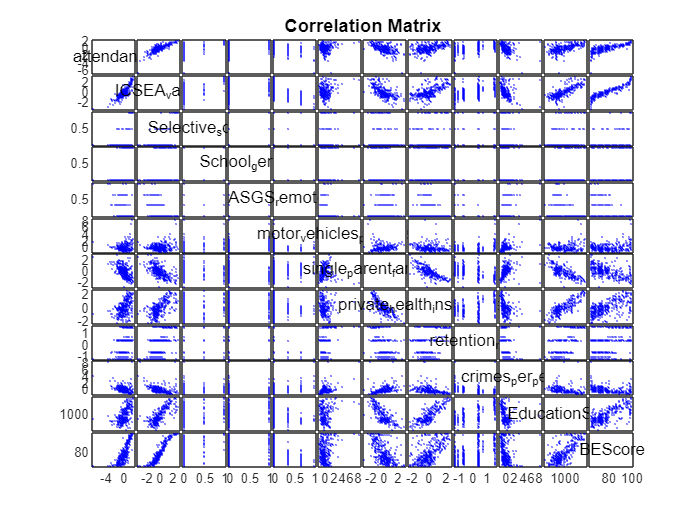


%% Create a disaply a matrix of the linear correlation betwwwn each of the model predictors
[h,ax] = gplotmatrix(model_table_predictors{:,:},[],[],[],[],[],[],'variable',xnames);
title('Correlation Matrix');


% Summarise Model Output - Regression Model
fprintf('The regression model returned a r^2 value of %.2f for the training dataset', regressionModel.LinearModel.Rsquared.Ordinary);

The regression model returned a r^2 value of 0.79 for the training dataset

fprintf('The regression model returned an adjusted r^2 value of %.2f for the training dataset', regressionModel.LinearModel.Rsquared.Adjusted);

The regression model returned an adjusted r^2 value of 0.78 for the training dataset

fprintf('The regression model returned an RMSE of %.2f for the training dataset', validationRMSE);

The regression model returned an RMSE of 0.47 for the training dataset

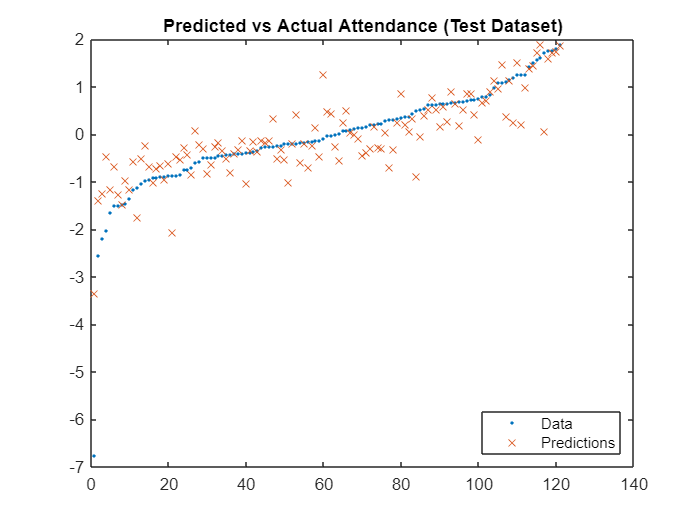


% Plot the Regression Model Predicted vs Actual - Test Data
plot([1:size(TEST_TABLE.attendance)], TEST_TABLE.attendance,'.', [1:size(TEST_TABLE.attendance)], predictedRegressionOutput,'x');
legend('Data','Predictions', 'Location', 'southeast');
title('Predicted vs Actual Attendance (Test Dataset)');

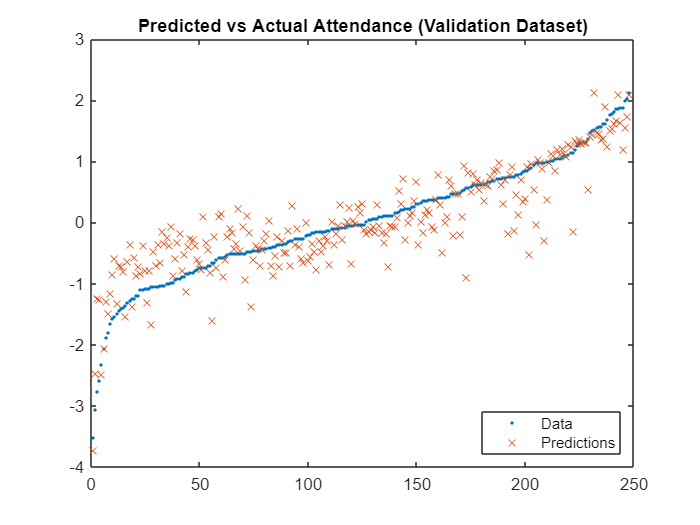


% Plot the Regression Model Predicted vs Actual - Test Data
plot([1:size(TRAIN_TABLE.attendance)], TRAIN_TABLE.attendance,'.', [1:size(TRAIN_TABLE.attendance)], regressionModel.LinearModel.Fitted,'x');
legend('Data','Predictions', 'Location', 'southeast');
title('Predicted vs Actual Attendance (Validation Dataset)');


% Summarise Model Output - Classification Model
fprintf('The classification model returned an accuracy value of %.2f percent for the training dataset', classificationAccuracy * 100);

The classification model returned an accuracy value of 66.94 percent for the training dataset

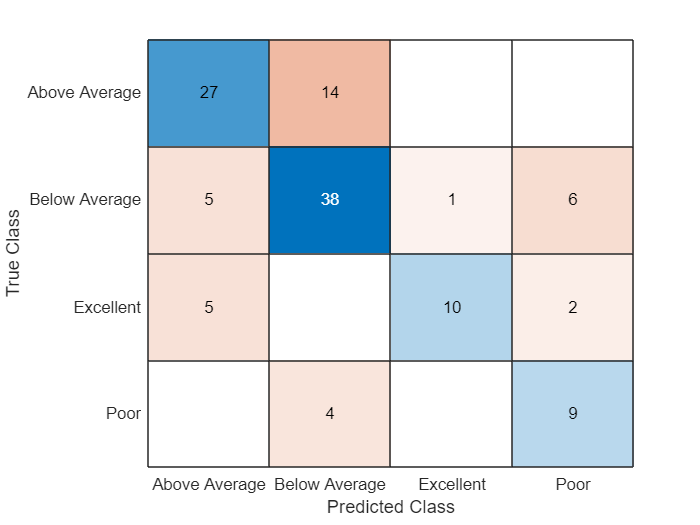

confusionchart(TEST_TABLE.attendance_cls, convertCharsToStrings(predictedClassificationOutput));


%%%%% Optimisations %%%%% 

%%%%%%%%%%%%%% Attempt to Optimise the Regression Model %%%%%%%%%%%%%%

% Remove low correlated predictors from model (< 0.4 in correlation table)
optimised_regression_table = removevars(model_table, ["School_gender", "motor_vehicles_per_house"]);

% Partition more data into training to increase accuracy (80% 20%) split 
cv_optimised_r          =  cvpartition(height(optimised_regression_table),'HoldOut', 0.20);
OPTIMISED_R_TRAIN_TABLE =  optimised_regression_table(cv_optimised_r.training, :);
OPTIMISED_R_TEST_TABLE  =  optimised_regression_table(cv_optimised_r.test, :);

% Train and test regression model on optimised data set
[optimisedRegressionModel, optimisedValidationRMSE] = trainOptimisedRegressionModel(OPTIMISED_R_TRAIN_TABLE);
optimisedPredictedRegressionOutput = optimisedRegressionModel.predictFcn(OPTIMISED_R_TEST_TABLE);

fprintf('The optimised regression model returned a r^2 value of %.2f for the training dataset', optimisedRegressionModel.LinearModel.Rsquared.Ordinary);

The optimised regression model returned a r^2 value of 0.76 for the training dataset

fprintf('The optimised regression model returned an adjusted r^2 value of %.2f for the training dataset', optimisedRegressionModel.LinearModel.Rsquared.Adjusted);

The optimised regression model returned an adjusted r^2 value of 0.76 for the training dataset

fprintf('The optimised regression model returned an RMSE of %.2f for the training dataset', optimisedValidationRMSE);

The optimised regression model returned an RMSE of 0.56 for the training dataset

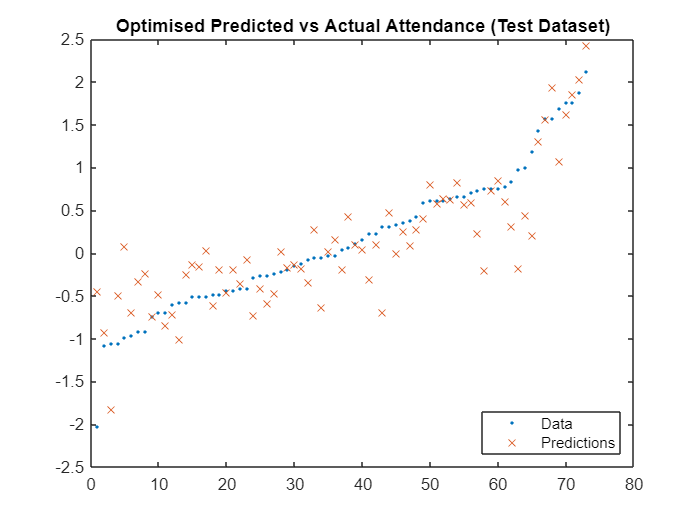


% Plot the Optimised Regression Model Predicted vs Actual - Test Data
plot([1:size(OPTIMISED_R_TEST_TABLE.attendance)], OPTIMISED_R_TEST_TABLE.attendance,'.', [1:size(OPTIMISED_R_TEST_TABLE.attendance)], optimisedPredictedRegressionOutput, 'x');
legend('Data','Predictions', 'Location', 'southeast');
title('Optimised Predicted vs Actual Attendance (Test Dataset)');


%%%%%%%%%%%%%% Attempt to Optimise the Classification Model %%%%%%%%%%%%%%

% Divide the categories into a binary classifcation 
% This has been done by attendace mean(normalized to equal 0)
belowAvgIndex = model_table.attendance <= 0;
model_table.attendance_cls(~belowAvgIndex, :) = "Above Average";
model_table.attendance_cls(belowAvgIndex, :) = "Below Average";

% Partition more data into training to increase accuracy (75% 25%) split 
cv_optimised_c        =  cvpartition(height(model_table),'HoldOut', 0.25);
OPTIMISED_C_TRAIN_TABLE =  model_table(cv_optimised_c.training, :);
OPTIMISED_C_TEST_TABLE  =  model_table(cv_optimised_c.test, :);

[optimisedClassificationModel, optimisedClassificationAccuracy] = trainOptimisedClassificationModel(OPTIMISED_C_TRAIN_TABLE);
optimisedPredictedClassificationOutput = optimisedClassificationModel.predictFcn(OPTIMISED_C_TEST_TABLE);

fprintf('The optimised classification model returned an accuracy value of %.2f percent for the training dataset', optimisedClassificationAccuracy * 100);

The optimised classification model returned an accuracy value of 79.42 percent for the training dataset

fprintf('The optimised classification model returned an accuracy value of %.2f percent more accurate then the original model', (((optimisedClassificationAccuracy) - (classificationAccuracy)) * 100));

The optimised classification model returned an accuracy value of 12.49 percent more accurate then the original model

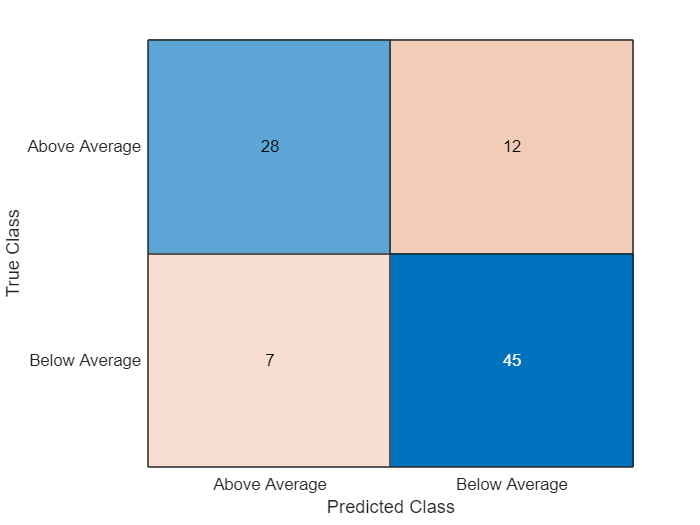

confusionchart(OPTIMISED_C_TEST_TABLE.attendance_cls, convertCharsToStrings(optimisedPredictedClassificationOutput));